## Space Vehicle Design Script

Load configurations and combine the structs for the SV

% Initialize the model structure
clc; clear all;
% Load config struct for the Bus
bus = config_bus();
iso = config_Iso_Obench();
payload  = config_Payload();
% Combine the structures
SV = fem.merge_fem_models(bus, iso, payload);

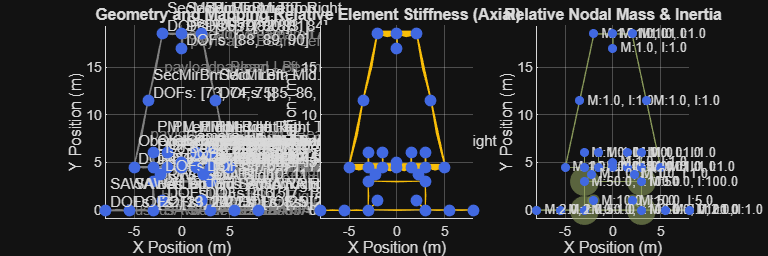

% Visualize the combined spacecraft FEM model
fem.plot_fem_model(SV);

Visualize the SV modes

% fem.plot_mode_shapes(SV,[SV.fn(30),SV.fn(41)])

Simulate disturbances from the RWAs

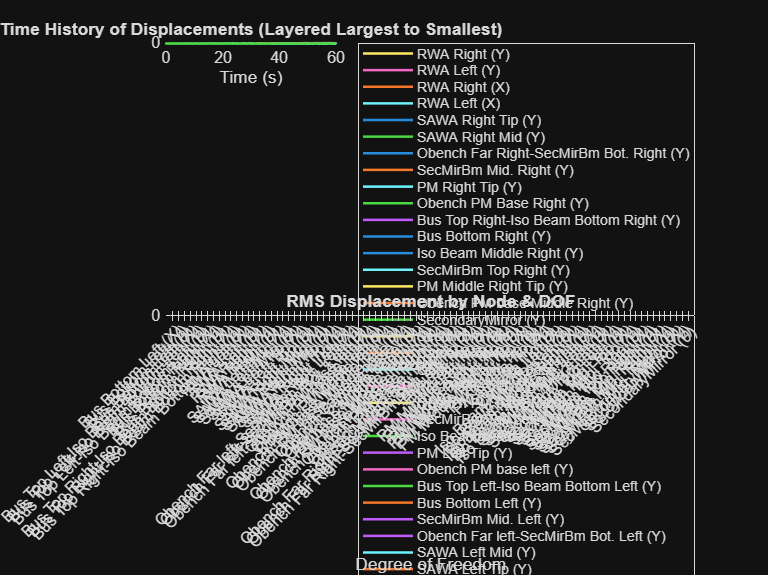

% Load options profile
% Compute the spacecraft response under reaction-wheel disturbances
options_rwa_disturbances = options_rwa_disturbances();
[X_rms_rwa_dist, X_rwa_dist] = fem.calculate_plot_rms(SV, options_rwa_disturbances);

Calculate pointing error of the mirrors

% Establish optical nodes
optical_nodes.sm_id = "SecondaryMirror";
optical_nodes.pm_ids = {"PM Left Tip", "PM Middle Left Tip", "PM Middle Right Tip", "PM Right Tip"};
[pointing_error, components] = fem.calculate_optical_pointing_error(SV, X_rwa_dist, optical_nodes);

Secondary Mirror Disturbance Analysis: Build State Space

% Define damping and motor disturbance
zeta = 0.01;
options_sm_motor = options_sm_motor();

options_sm_motor = struct with fields:
         t: [0 1.0000e-03 0.0020 0.0030 0.0040 0.0050 0.0060 0.0070 0.0080 0.0090 0.0100 0.0110 0.0120 0.0130 0.0140 0.0150 0.0160 0.0170 0.0180 0.0190 0.0200 0.0210 0.0220 0.0230 0.0240 0.0250 0.0260 0.0270 0.0280 0.0290 0.0300 … ] (1×60001 double)
         z: 0.0100
    forces: [1×1 struct]


% Call helper function to generate SS matrecies
[A, B, C, D] = fem.build_state_space(SV, options_sm_motor, optical_nodes, zeta);

Compute PSD Response of the System

% Define range of frequencies
f_range = linspace(10, 100, 1000)';
rms_error = fem.compute_psd_rms(A, B, C, D, f_range);